clc;
clear;
close all;

## Esercizio 1

generi casualmente un numero n intero compreso tra −50 e −1. Dopo aver verificato che il numero inserito sia anche divisibile per 5, si  costruisca e si visualizzi la matrice X fatta nel seguente modo

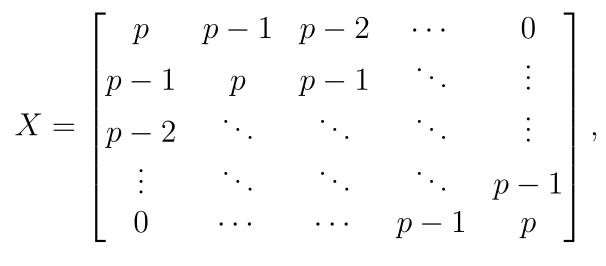

dove, p = − n/5 . Se il numero generato n non dovesse verificare le condizioni richieste, dovrà esserne generato uno nuovo fino a quando non si ottiene un numero consentito.

n = -5 * randi([1 10], 1);
p = -1 * (n/5)

p = 8


X = ones(p + 1);

for i = 1:p+1
    if i ~= 1 
        x = p-i+1 : 1 : p;
    else
        x = p;
    end
    y = p-1 : -1 : i - 1;

    %[x y]

    X(i, :) = [x, y];
end

X

X =      8     7     6     5     4     3     2     1     0
     7     8     7     6     5     4     3     2     1
     6     7     8     7     6     5     4     3     2
     5     6     7     8     7     6     5     4     3
     4     5     6     7     8     7     6     5     4
     3     4     5     6     7     8     7     6     5
     2     3     4     5     6     7     8     7     6
     1     2     3     4     5     6     7     8     7
     0     1     2     3     4     5     6     7     8


clc;
clear;
close all;

## Esercizio 2

rei un test per la risoluzione di un sistema lineare Ax = b con i metodi iterativi di Jacobi e Gauss-Seidel. In particolare:

• generare le matrici dei coefficienti del sistema di dimensione crescente da 10 a 100 con passo 10, contenenti numeri pseudo-casuali reali compresi tra −30 e 30;

• rendere la matrice strettamente diagonalmente dominante;

• imporre una soluzione nota x di elementi uguali a 1 e calcolare il corrispondente termine noto b;

• calcolare la soluzione xj del sistema utilizzando il metodo di Jacobi e la soluzione xgs del sistema utilizzando il metodo di Gauss-Seidel.

• infine, calcolare e visualizzare una tabella in cui ogni riga contiene: la dimensione della matrice, l’errore relativo tra la soluzione vera x e quella ottenuta xj , il numero di iterazioni kj , l’errore relativo tra la soluzione vera x e quella ottenuta xgs , il numero di iterazioni kgs .

Per entrambi i metodi, impostare un vettore iniziale x(0) con entrate casuali tra 0 e 1, una tolleranza tol = 10−6 e un numero massimo di iterazioni kmax = 200.

Le funzioni

• [x_j, k_j] = jacobi(A,b,x0,tol,kmax))

• [x_gs, k_gs] = gs(A,b,x0,tol,kmax))

dovranno essere allegate alla fine dello script.

iMin = -30;
iMax = 30;
tol = 10e-6;
kmax = 200;

k = 1;

for i = 10 : 10 : 100
    % Genero progressivamente le matrici
    A = (iMax-iMin) * rand(i) + iMin;

    % Rendo la matrice diagonalmente dominante
    A = A - diag(diag(A));
    s = sum(abs(A));
    s = s + 0.1;
    A = A + diag(s);

    % Costruisco x
    x = ones(i, 1);

    % Calcolo b
    b = A * x;

    % Jacobi
    [xj, kj(k)] = jacobi(A, b, tol, kmax);

    errRelJ(k) = norm(x - xj) / norm(x);

    % Gauss-Seidel
    x0 = randi([0 1], size(A, 1), 1);

    [xgs, kgs(k)] = gauss_seidel(A, b, x0, tol, kmax);

    errRelGS(k) = norm(x - xgs) / norm(x);

    k = k + 1;
end

dim = 10 : 10 : 100;

t = table(dim', errRelJ', kj', errRelGS', kgs', 'VariableNames', {'Dimensione A', 'errRelJ', 'kj', 'errRelGS', 'kgs'});
disp(t)

    Dimensione A     errRelJ      kj     errRelGS     kgs
    ____________    __________    __    __________    ___

         10          6.308e-07    15    6.4257e-07     7 
         20          2.318e-07    11    2.9128e-07     7 
         30         5.8272e-08    10    1.0757e-07     7 
         40         1.3323e-07     9    3.2329e-07     6 
         50         6.1621e-08     9    3.0414e-07     6 
         60         3.5747e-08     9    8.9035e-08     6 
         70         1.6052e-07     8    4.5957e-08     6 
         80         9.7243e-08     8    5.5744e-08     6 
         90         4.0203e-08     8    2.8423e-08     6 
        100         4.3512e-08     8    2.4866e-08     6 



clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

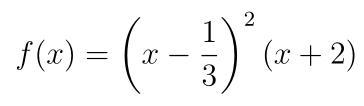

In particolare:

• determinare l’intervallo della forma [ℓ, ℓ + 1], con ℓ intero, che contiene la radice positiva di f ;

• determinare l’approssimazione xn utilizzando il metodo di Newton, con valore iniziale x(0) = ℓ;

• determinare l’approssimazione xc utilizzando il metodo delle corde, con valore iniziale x(0) = ℓ e m = f ′ (ℓ);

Per entrambi i metodi, impostare una tolleranza tol = 10e−5 e un numero massimo di iterazioni kmax = 150.

Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le approssimazioni ottenute. Il grafico dovrà essere corredato da un titolo e una legenda.

Le funzioni

• [xn ,kn ] = newton(f,fder,x0,tol,kmax)

• [xb ,kb ] = corde(f,m,x0,tol,kmax)

dovranno essere allegate alla fine dello script.

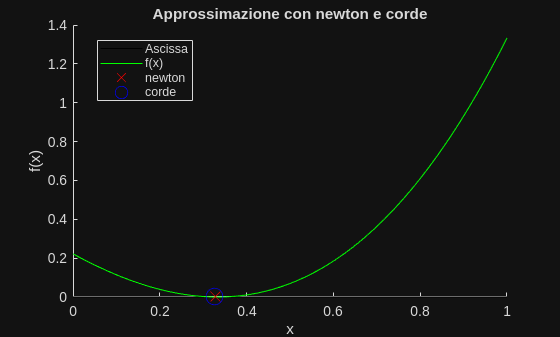

tau = 10e-5;
kmax = 150;

f = @(x) (x - (1/3)).^2 .* (x + 2);
fder = @(x) 2.*(x-(1/3)).*(x + 2) + (x-(1/3)).^2;

l = 0;
m = fder(l);

[xn, kn] = newton(f, fder, l, tau, kmax);
[xc, kc] = corde(f, m, l, tau, kmax);

figure;
hold on;

x = linspace(-l, l+1);

xlabel("x");
ylabel("f(x)");
title("Approssimazione con newton e corde");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "xr", "DisplayName", "newton", "MarkerSize", 10);
plot(xc, f(xc), "ob", "DisplayName", "corde", "MarkerSize", 12);

legend("Location", "best");
hold off;

function [x, k] = jacobi(A, b, tau, k_max)

    % jacobi: metodo per trovare un'approssimazione delle radici tramite 
    % iterazioni successive di un sistema di equazioni lineari
    %   [x, k] = jacobi(A, b, x0, tau, k_max) restituisce le soluzioni
    %   della matrice e il numero di iterazioni effettuate.


    % tau e k_max sono le condizioni d'arresto:
        % tau = tolleranza
        % k_max = iterazioni massime
    
    % Controllo che la matrice non sia singolare
    if (abs(det(A)) < 1e-12)
        error("Il sistema può non ammettere soluzioni");
    end
    
    
    x0 = zeros(size(A, 1), 1);
    x0(1) = 1;
    
    % A = D - E - F
    
    % diag() restituisce un vettore, quindi diag() su di esso mi rende una 
    % matrice con tutti 0 tranne la diagonale, che avrà i valori del
    % vettore
    D = diag(diag(A));
    
    %E = (tril(A) - D) * -1;
    E = -tril(A, -1);
    
    F = -triu(A, 1);
    
    %Bj = D^-1 * (E + F);
    Bj = D\(E + F);
    
    %fj = D^-1 * b;
    fj = D\b;
    
    % Un MLS1 converge quando il rho della matrice di iterazione è < 1
    rho = abs(eigs(Bj, 1, 'largestabs')); % anche con largestabs restituisce l'autovalore col suo segno originario
    
    if (rho >= 1)
        error("Il metodo non converge");
    end
    

    % Inizializzazione variabili
    x_old = x0;
    flag = true;
    k = 1;

    while (flag)
        % Condizione di stop per massimo numero di iterazioni
        if (k >= k_max)
            warning("k_max è stato raggiunto");
            break;
        end
    
        x_new = Bj * x_old + fj;
    
        % Condizione di stop per soluzioni accettabili, cioè abbastanza
        % vicine alla soluzione reale
        if (norm(x_new - x_old) < tau)
            flag = false;
        else
            % Aggiornamento variabili per l'iterazione successiva
            x_old = x_new;
            k = k + 1;
        end
    end
    
    x = x_new;
end

function [x, k] = gauss_seidel(A, b, x0, tau, k_max)

    % gauss_seidel: metodo per trovare un'approssimazione delle radici 
    % tramite iterazioni successive di un sistema di equazioni lineari
    %   [x, k] = gauss_seidel(A, b, x0, tau, k_max) restituisce le 
    % soluzioni della matrice e il numero di iterazioni effettuate.

    % tau e k_max sono le condizioni d'arresto:
        % tau = tolleranza
        % k_max = iterazioni massime
        % x0 = vettore di grandezza size(A, 1) di numeri interi
    
    % Controllo che la matrice non sia singolare
    if (abs(det(A)) < 1e-12)
        error("Il sistema può non ammettere soluzioni");
    end
    
    % A = D - E - F
    
    % diag() restituisce un vettore, quindi diag() su di esso mi rende una 
    % matrice con tutti 0 tranne la diagonale, che avrà i valori del
    % vettore
    D = diag(diag(A));
    
    %E = (tril(A) - D) * -1;
    E = -tril(A, -1);
    
    F = -triu(A, 1);
    
    %Bgs = (D - E)^-1 * F;
    Bgs = (D - E) \ F;
    
    %fgs = (D - E)^-1 * b;
    fgs = (D - E) \ b;
    
    % Un MLS1 converge quando il rho della matrice di iterazione è < 1
    rho = abs(eigs(Bgs, 1, 'largestabs')); % anche con largestabs restituisce l'autovalore col suo segno originario
    
    if (rho >= 1)
        error("Il metodo non converge");
    end
    

    % Inizializzazione variabili
    x_old = x0;
    flag = true;
    k = 1;


    while (flag)

        % Condizione di stop per massimo numero di iterazioni
        if (k >= k_max)
            warning("k_max è stato raggiunto");
            break;
        end
    
        % Passo iterativo Gauss-Seidel
        x_new = Bgs * x_old + fgs;
    
        % Condizione di stop per soluzioni accettabili, cioè abbastanza
        % vicine alla soluzione reale
        if (norm(x_new - x_old) < tau * norm(x_new))
            flag = false;
        else
            % Aggiornamento variabili per l'iterazione successiva
            x_old = x_new;
            k = k + 1;
        end
    end
    
    x = x_new;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xc, kc] = corde(f, m, x0, tau, kmax)
    
    % corde: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xc, kc] = corde(f, m, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Controllo che il punto iniziale sia già una radice
    if(abs(f(x0)) < tau)
        xc = x0;
        kc = 1;
        return;
    end
    
    % Controllo che m non sia tendente a 0
    if abs(m) < tau
        error("Valore di m troppo vicino a 0");
    end

    % Inizio algoritmo iterativo da k a kmax
    for kc = 1 : kmax

        % Formula corde
        xc = x0 - f(x0) / m;

        % Condizioni di arresto
        if abs(f(xc)) < tau || abs(xc - x0) < tau * abs(x0)
            return;
        end

        % Aggiorno variabile
        x0 = xc;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end